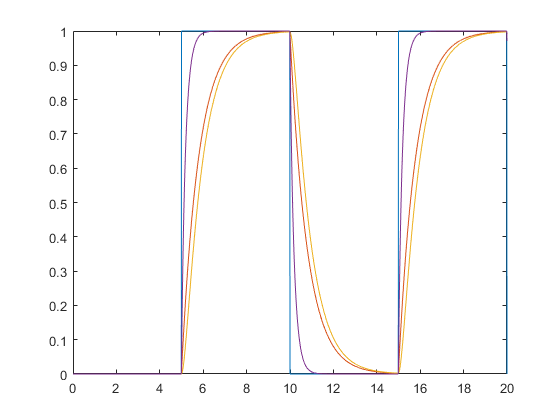

% Simulación de un motor
load('A3_CreateReferenceLowPassFilter.mat')
% Square
Ts = 0.01;
[u,t] = gensig("square",10,20, Ts);
y = lsim(H, u, t, 'zoh');
y2 = lsim(tfz_cl, y, t, 'zoh');
y2_sf = lsim(tfz_cl, u, t, 'zoh');

figure;
plot(t, u); hold on;
plot(t, y)
plot(t, y2)
plot(t, y2_sf)


tfzH = minreal(H*tfz_cl)

tfzH =
 
  From input "u1" to output:
  0.0001799 + 0.000197 z^-1 - 0.0001457 z^-2 - 0.0001628 z^-3
  -----------------------------------------------------------
           1 - 2.825 z^-1 + 2.658 z^-2 - 0.8327 z^-3
 
Sample time: 0.01 seconds
Discrete-time transfer function.



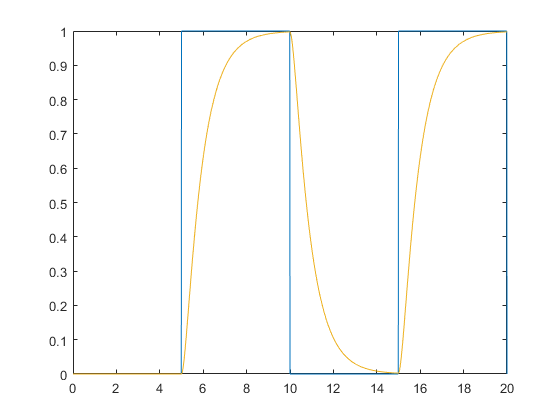

y3 = lsim(tfzH, u, t, 'zoh');

figure;
plot(t, u); hold on;
plot(t, y2)
plot(t, y3)


% Ecuaciones en diferencias
[num,den] = tfdata(tfzH, 'v')

num = 	1.0e+-3 *

    0.1799    0.1970   -0.1457   -0.1628


den =     1.0000   -2.8253    2.6580   -0.8327


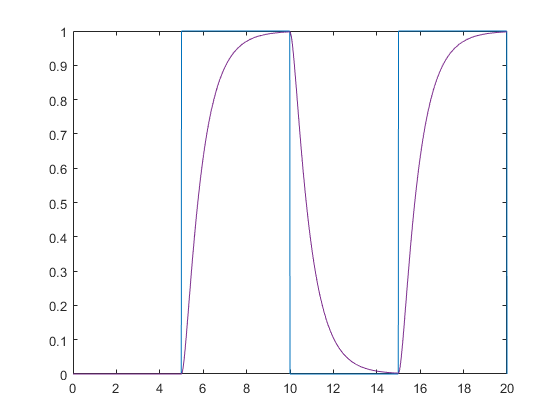


w = zeros(length(den),1);
wr = zeros(length(num),1);

y4 = zeros(length(t), 1);
for i=1:length(t)
    wr(1) = u(i);
    for j=2:length(den)
        w(1) = w(1) - den(j)*w(j);
    end
    for j=1:length(num)
        w(1) = w(1) + num(j)*wr(j);
    end
    y4(i) = w(1);
    for j=flip(1:length(den)-1)
        w(j+1) = w(j);
    end
    for j=flip(1:length(num)-1)
        wr(j+1) = wr(j);
    end
    w(1) = 0;
end

figure;
plot(t, u); hold on;
plot(t, y2)
plot(t, y3)
plot(t, y4)